# AT Primer

## Introduction

The Accelerator Toolbox (AT) is a toolbox of functions in Matlab for charged particle beam simulation. It was created by Andrei Terebilo in the late 1990's. The original papers ([[1]](https://www.slac.stanford.edu/pubs/slacpubs/8500/slac-pub-8732.pdf), [[2]](https://inspirehep.net/files/298dd81ab9ce89bfb2a42442b46b0379)) still serve as a good introduction to AT. The version described in those papers is AT1.3, the latest version produced by Terebilo. The next version of AT is considered AT2.0. Here we provide examples showing some of the changes from AT1.3, but also serving as an introduction for someone just starting AT.

## Coordinate system

The 6-d phase space coordinates used in AT are as follows:


$$$\vec Z = \pmatrix{x\cr \frac{p_x}{p_0}=x'(1+\delta) \cr y \cr \frac{p_y}{p_0}=y'(1+\delta) \cr \delta=\frac{\left(p_z-p_0\right)}{p_0} \cr c\tau}$
$$


$p_0$ is the reference momentum, $\tau$ is the time lag relative to the ideal particle.

## Creation of Elements and Lattices

A lattice in AT is a Matlab column cell array containing the lattice elements. These elements may be created using element creation functions. These functions output element structures. For example, a quadrupole may be created with the function **atquadrupole**:

QF=atquadrupole('QF',0.5,1.2,'StrMPoleSymplectic4Pass')

QF = struct with fields:
        FamName: 'QF'
     PassMethod: 'StrMPoleSymplectic4Pass'
         Length: 0.5000
          Class: 'Quadrupole'
              K: 1.2000
       PolynomB: [0 1.2000]
       PolynomA: [0 0]
       MaxOrder: 1
    NumIntSteps: 10


We note that the family name of this quadrupole is 'QF' and the pass method is StrMPoleSymplectic4Pass. The fields following are parameters necessary to be able to pass an electron through this quadrupole (i.e., the set of arguments required by the pass method). We now create some other elements needed in a FODO lattice:

Dr=atdrift('Dr',0.5);
HalfDr=atdrift('Dr2',0.25);
QD = atquadrupole('QD',0.5,-1.2);
Bend=atsbend('Bend',1,2*pi/40);

In addition to **atquadrupole** that we already saw, we have created a drift (region with no magnetic field), using **atdrift**. Besides the family name, the only other needed field is the length. Since we split the cell in the center of the drift, we have also created a half drift element. The drifts are 0.5 meters long and the half drift is 0.25 meters long. We have defined a sector dipole, or bend magnet using **atsbend**. The family name is 'Bend'. The second field is the length of the magnet and we have given it a length of 1 meter. Next is the bending angle. We have defined just an arc of a FODO lattice here, so we don't have to bend by all of $$2\pi$$ here. We choose to have 20 total such arcs, for a realistic field strength, and thus we define the bending angle to be $$2\pi/40$$ since there are two bends per cell. The default pass method for the bend is 'BndMPoleSymplectic4Pass'. This is a 4th order symplectic integrator. We outline the integrators in a later section.

A cell of a FODO lattice may now be constructed as follow:

FODOcell={HalfDr;Bend;Dr;QF;Dr;Bend;Dr;QD;HalfDr};

As mentioned, this cell is only 1/20 of a FODO lattice. The entire lattice may be created by repeating this cell 20 times as follows

FODO=repmat(FODOcell,20,1);

Finally, we create a RingParam element and add it to our lattice. This allows us to give a name to the lattice and set the ring energy. This is done as follows:

RP=atringparam('Simple FODO lattice',1e9);
FODO=[{RP};FODO];

The energy of a lattice may be retrieved with the function **atenergy**. Thus

atenergy(FODO)

ans = 1.0000e+09

Another way to set the energy of a lattice uses the function **atsetenergy**. This puts an energy field in all elements and set it to the requested value. The energy element is required in the RF cavities and also in other magnets such as dipoles and quadrupoles in the case that classical radiation effects are included.

We have now created a valid AT lattice, using drifts, dipoles, and quadrupoles. We will later add some sextupoles to this lattice, and also an RF cavity, but one could track particles through this lattice, as is.

For completeness, we list all of the AT element creation functions: **ataperture**, **atbaseelem**, **atcorrector**, **atdampMatElem**, **atdrift**, **atidtable**, **atM66**, **atM66Tijk**, **atmarker**, **atmonitor**, **atmultipole**, **atquadrupole**, **atQuantDiff**, **atrbend**, **atrfcavity**, **atringparam**, **atsbend**, **atsextupole, atskewquad**, **atsolenoid**, **atthinmultipole**, **atwiggler**.

## Lattice Querying and Manipulation

There are many parameters in a storage ring lattice. We need tools to view these parameters and to change them.

We have seen how to concatenate elements to form a lattice. To extract elements, there are two approaches, one may use either indices giving the explicit element numbers, or one can use a logical mask. Thus, to extract the 4th element of our FODOCell lattice, (a focusing quadrupole, 'QF'), one may either write 'FODOcell{4}'. Likewise, we may also construct a logical mask with:

mask=false(1,length(FODOcell));
mask(4)=true;

The command 'FODOCell(mask)' will also give the same 'QF' element.

Next, we describe three important functions for working with AT lattices: **atgetcells**, **atgetfieldvalues**, and **atsetfieldvalues.** **atgetcells** allows one to find the indices of elements in the lattice searching for various criteria. The second to allow extraction and setting of element parameters.

As a first example of **atgetcells** let us extract the indices of all of the QF's as follows

QFIndices = atgetcells(FODOcell,'FamName','QF')

QFIndices = 9×1 logical array
   0
   0
   0
   1
   0
   0
   0
   0
   0


where we see the 'QF' at element 4. To convert this logical mask to an index, use the **find** command.

find(QFIndices)

ans = 4

A new feature added to AT 2.0 is element classes. These are *Drift*, *Bend*, *Quadrupole*, *Sextupole*, *Octupole*, *Multipole*, *ThinMultipole*, *Wiggler*, *KickMap*, *RFCavity*, *QuantDiff*, *Monitor*, *Corrector*, *Solenoid*, *Matrix66*, *RingParam*. This allows us to get the indices for all of the quadrupoles with the command.

QuadIndices = atgetcells(FODO,'Class','Quadrupole')

QuadIndices = 181×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   1
   0


with the result

find(QuadIndices)

ans =      5
     9
    14
    18
    23
    27
    32
    36
    41
    45


showing the indices of both 'QF' and 'QD' in the FODO cell.

The reader can look further into the help for **atgetcells** by typing

help atgetcells

 atgetcells performs a search on MATLAB cell arrays of structures
 
  OK = atgetcells(RING, 'field')
    returns indexes of elements that have a field named 'field'
 
  OK = atgetcells(RING, 'field', VALUE1...)
    returns indexes of elements whose field 'field'
    is equal to VALUE1, VALUE2, ... or VALUEN. Where VALUE can either be
    character strings or a number. If its a character string REGULAR
    expressions can be used.
 
  OK = atgetcells(RING, 'field', @TESTFUNCTION, ARGS...)
    Uses the user-defined TESTFUNCTION to select array elements
    TESTFUNCTION must be of the form:
        OK=TESTFUNTION(ATELEM,FIELDVALUE,ARGS...)
 
  OK is a logical array with the same size as RING, refering to matching
  elements in RING
 
  See also atgetfieldvalues, atsetfieldvalues, 

to see other ways this function can be used, including the use of matching regular expressions.

The **atgetfieldvalues** command may be used to extract the fields with the elements. For example the quadrupole strengths may be retrieved using the command.

Kvals=atgetfieldvalues(FODO,QuadIndices,'PolynomB',{1,2})

Kvals =     1.2000
   -1.2000
    1.2000
   -1.2000
    1.2000
   -1.2000
    1.2000
   -1.2000
    1.2000
   -1.2000


The **atsetfieldvalues** command may be used to set the values of parameters. As a simple example, we may add some random errors to all the quadrupoles strengths:

Kvalserr=Kvals+0.2*(rand(length(Kvals),1)-0.5);
FODOerr=atsetfieldvalues(FODO,QuadIndices,'PolynomB',{1,2},Kvalserr);

Note that the output of **atsetfieldvalues** is another lattice structure, which here we call 'FODOerr' which has the quadrupole strengths 'Kvalserr'. Now we have both 'FODO' and 'FODOerr' in the Matlab workspace and we can examine them or do calculations for comparison.

Suppose we would like to plot the quadrupole strengths along the lattice. We first need to find the longitudinal position $$s$$ of each quadrupole. This may be done with the function **findspos**:

quadspos = findspos(FODO,QuadIndices);

The quadrupole strengths of 'FODO' and 'FODOerr' may now be plotted with:

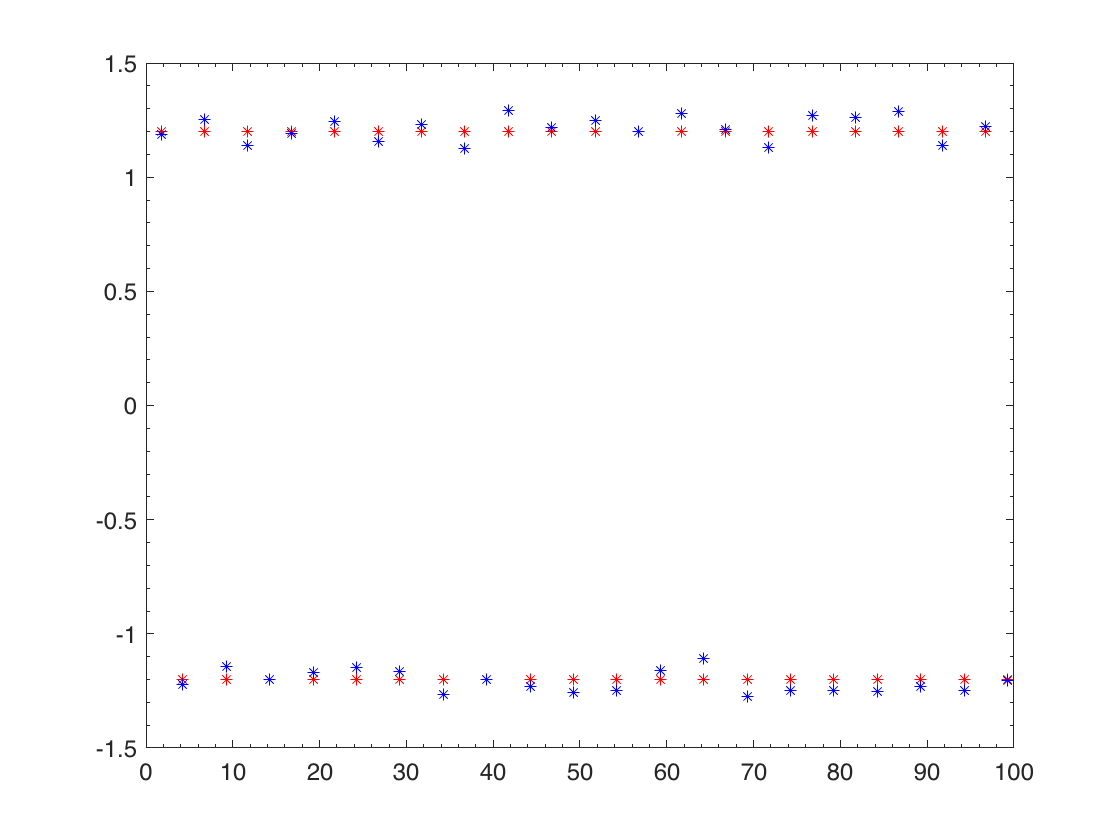

plot(quadspos,Kvals,'*r',quadspos,Kvalserr,'*b');

## Tracking

Once a lattice is defined, electrons may be tracked through it. **ringpass** is the function that does the tracking. An example of its use is as follows:

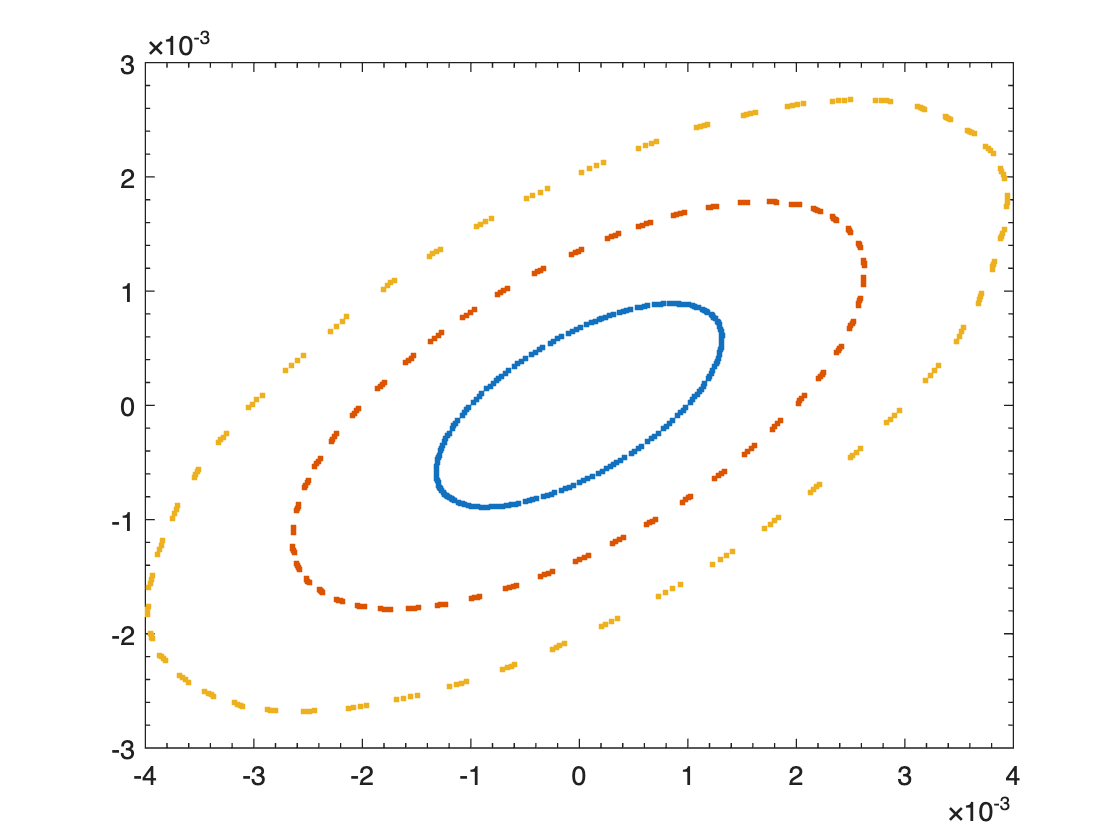

nturns=200;
Z01=[.001;0;0;0;0;0];
Z02=[.002;0;0;0;0;0];
Z03=[.003;0;0;0;0;0];
Z1=ringpass(FODO,Z01,nturns);
Z2=ringpass(FODO,Z02,nturns);
Z3=ringpass(FODO,Z03,nturns);
plot([Z1(1,:); Z2(1,:); Z3(1,:)]',[Z1(2,:); Z2(2,:); Z3(2,:)]','.')

In this example, we started with one initial condition, and all subsequent turns are returned by ringpass. We may also start with multiple initial conditions:

Z0=[.001;0;0;0;0;0]*(1:3);
Z200=ringpass(FODO,Z0,nturns);

Examining the variable Z200, we find

whos Z200

  Name      Size             Bytes  Class     Attributes

  Z200      6x600            28800  double              



The structure of this matrix is that the first three columns are the results of tracking for one turn the three initial conditions. The following columns are likewise grouped in threes with the subsequent results of tracking further turns. We may retrieve the same results as we had previously by extracting every third column vector as follows:

ZZ1=Z200(:,1:3:end);
ZZ2=Z200(:,2:3:end);
ZZ3=Z200(:,3:3:end);

Now the same plot as in Figure 2 results from the plot command

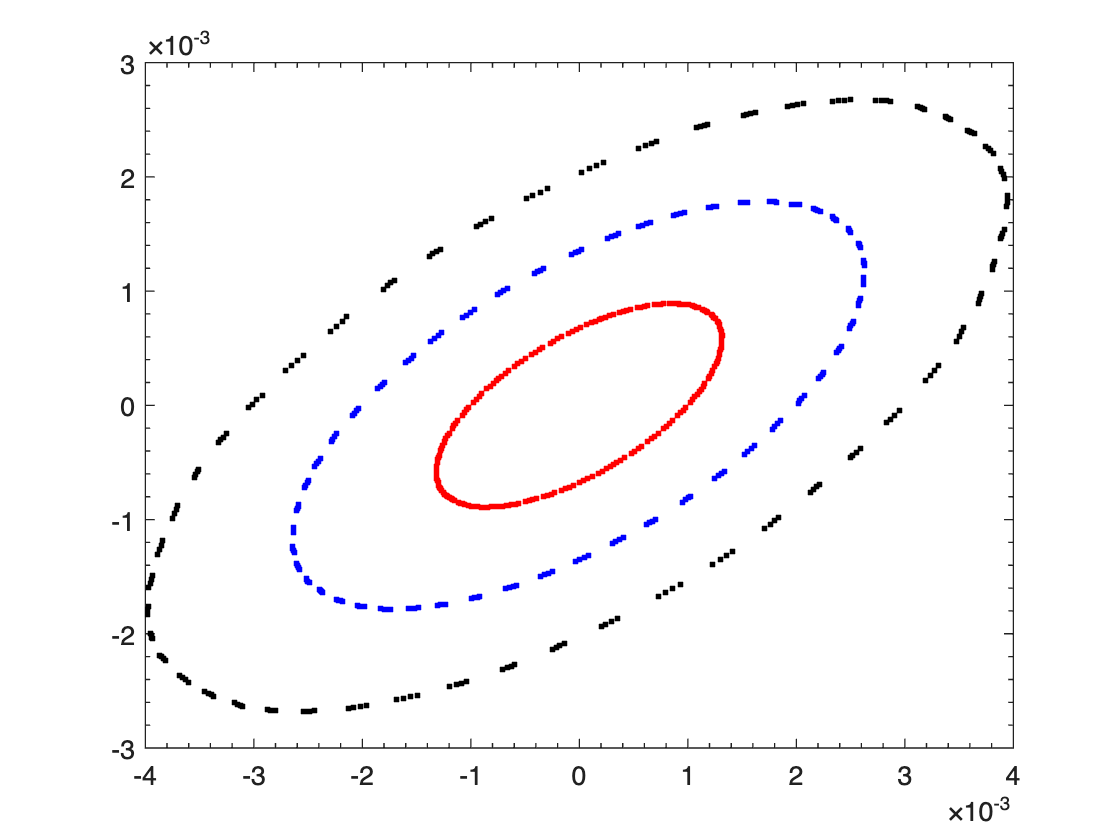

plot(ZZ1(1,:),ZZ1(2,:),'.r',ZZ2(1,:),ZZ2(2,:),'.b',ZZ3(1,:),ZZ3(2,:),'.k')

Another way to process the output of ringpass with multiple initial particles uses the **reshape** command

ZZ200=reshape(Z200,6,3,nturns);
ZZZ1=ZZ200(:,1,:);
ZZZ2=ZZ200(:,2,:);
ZZZ3=ZZ200(:,3,:);

This can be a convenient approach to process the results when many initial conditions are tracked.

## Computation of beam parameters

Now that particles can be tracked through the lattice, we can use the tracking to understand different properties of the lattice. First, we would like to understand the linear properties such as Twiss parameters, tunes, chromaticities, etc. These can all be calculated with the function **atlinopt6**.

ringdata=atlinopt6(FODO,'get_chrom');

Note first the input. The first is the FODO lattice we have created. The second argument asks for optional chromaticity computation. The default values for other optional arguments ask for the computation of on-momentum linear optics ($$\delta=0$$). 

The output is a structure with a 'tune' field:

ringdata.tune

ans =     0.2199    0.9178


ringdata.chromaticity

ans =    -6.3404   -6.1986


which tells us the tunes are $$\nu_x = 0.2199$ $ and $$\nu_y = 0.9178$$.

How did AT calculate these quantities? Without digging into the details of **atlinopt6**, you could still figure it out, just based on the ability to track with the **ringpass** function. In fact, AT computes the one-turn transfer matrix by tracking several initial conditions and differentiating. The one-turn transfer matrix (here we focus on 4x4) is computed with the function **findm44** called by **atlinopt6**. Calling this on the FODO lattice, we find

findm44(FODO,0)

ans =    -0.6519    1.9098         0         0
   -0.8743    1.0274         0         0
         0         0   -0.1807   -3.2483
         0         0    0.4147    1.9197


The 0 as the second argument tells us to compute with $$\delta=0$$. We note that the ring is uncoupled, and computing the eigenvalues of submatrices, we derive the tunes reported by **atlinopt6** above.

Computing the tunes with varying initial $$\delta$$ allows the computation of the chromaticity.

Now, suppose we would like to change the tunes in our FODO lattice. We know that we should change the quadrupole strengths, but we may not know exactly what values to use.

Here we reach the question of tuning. How do we set the parameters for these quadrupoles in order to correct the tunes? In principle we have the tools that we need. We can set the values of the quadrupoles using the function **atsetfieldvalues** and then recompute the chromaticity with **atlinopt6**. But we still don't know what values to actually give the quadrupoles. One could compute the value, or instead use an optimization routine to vary the values until the correct output tunes are achieved. This is the approach followed with the function **atfittune**.

This allows you to vary quadrupole strengths until the desired tune values are reached. It is used as follows

FODO2=atfittune(FODO,[0.15,0.75],'QF','QD');

which would set the tunes to $$\nu_x = 0.15$$ and $$\nu_y = 0.75$$ using the quadrupoles QF and QD. When we actually try this, and compute the linear optics, we find the result

ringdata2=atlinopt6(FODO2);
ringdata2.tune

ans =     0.1511    0.7508


We see that the requested values have almost been reached, but not exactly. A second call to **atfittune** gives:

FODO2=atfittune(FODO2,[0.15,0.75],'QF','QD');
ringdata2=atlinopt6(FODO2);
ringdata2.tune

ans =     0.1500    0.7500


Giving satisfactory results for the tunes.

Now, in case you have some experience with storage ring dynamics, you will know that these negative chromaticity values will lead to instability and thus our FODO lattice, as is, is not acceptable. To fix this problem, we add sextupoles to our lattice. We define a focusing and defocussing sextupoles (0.1 meter long) as follows:

SF=atsextupole('SF',0.1,1);
SD=atsextupole('SD',0.1,-1);

Now we want to add these to the lattice at locations where they will be effective. We will put them in the middle of the 0.5 meter drift sections: SF before the QF and SD before the QD. Let's locate the drifts:

find(atgetcells(FODOcell,'FamName','DR'))

ans =      3
     5
     7


We will insert SF in the middle of element 3 and SD in the middle of element 7. 

FODOcellSext=atinsertelems(FODOcell,[3 7], 0.5, {SF,SD});

And now we can define our lattice cell with sextupoles as follows:

FODOSext=[{RP};repmat(FODOcellSext,20,1)];
ringdataS=atlinopt6(FODOSext,'get_chrom');
ringdataS.tune

ans =     0.2199    0.9178


ringdataS.chromaticity

ans =    -4.9367   -5.6504


The tunes of FODOSext are identical to the ones of FODO. Now we need to tune the sextupoles. For this, we will use the function **atfitchrom**. This function works analogously to **atfittune** except the sextupoles are varied instead of the quadrupoles to fit the chromaticity. Applying this function (twice to get a more precise result):

FODOSext=atfitchrom(FODOSext,[0.5 0.5],'SF','SD');
FODOSext=atfitchrom(FODOSext,[0.5 0.5],'SF','SD');

After changing the tunes and fixing the chromaticities, we find

ringdataS=atlinopt6(FODOSext,'get_chrom');
ringdataS.tune

ans =     0.2199    0.9178


ringdataS.chromaticity

ans =     0.4997    0.4997


**atlinopt6** has a second output argument to give the linear optics parameters that vary around the ring. These are the Twiss parameters, dispersions, phase advance, and coupling parameters. To compute these around the ring, we need to give the indices for the reference points. To compute them at all lattice elements, we call

[ringdata,elemdata]=atlinopt6(FODOcellSext,1:length(FODOcellSext)+1);

Examining 'elemdata', we find:

elemdata

elemdata = 14×1 struct array with fields:
    R
    M
    A
    mu
    SPos
    ClosedOrbit
    alpha
    beta
    Dispersion


- 'SPos' is the  $$s$$ position,

- 'ClosedOrbit' is the $$x,x',y,y'$$ coordinate vector of the closed orbit,

- 'Dispersion' is the $$\eta_x,\eta'_x,\eta_y,\eta'_y$$ coordinate vector of the dispersion,

- 'M' is the local $$4\times 4$$ transfer matrix,

-  'beta' gives the horizontal and vertical $$\beta$$ functions,

- 'alpha' gives the $$\alpha_{x,y}$$ Twiss parameters,

- 'mu' gives the phase advances.

Let us use these results to plot the beta functions around the ring.

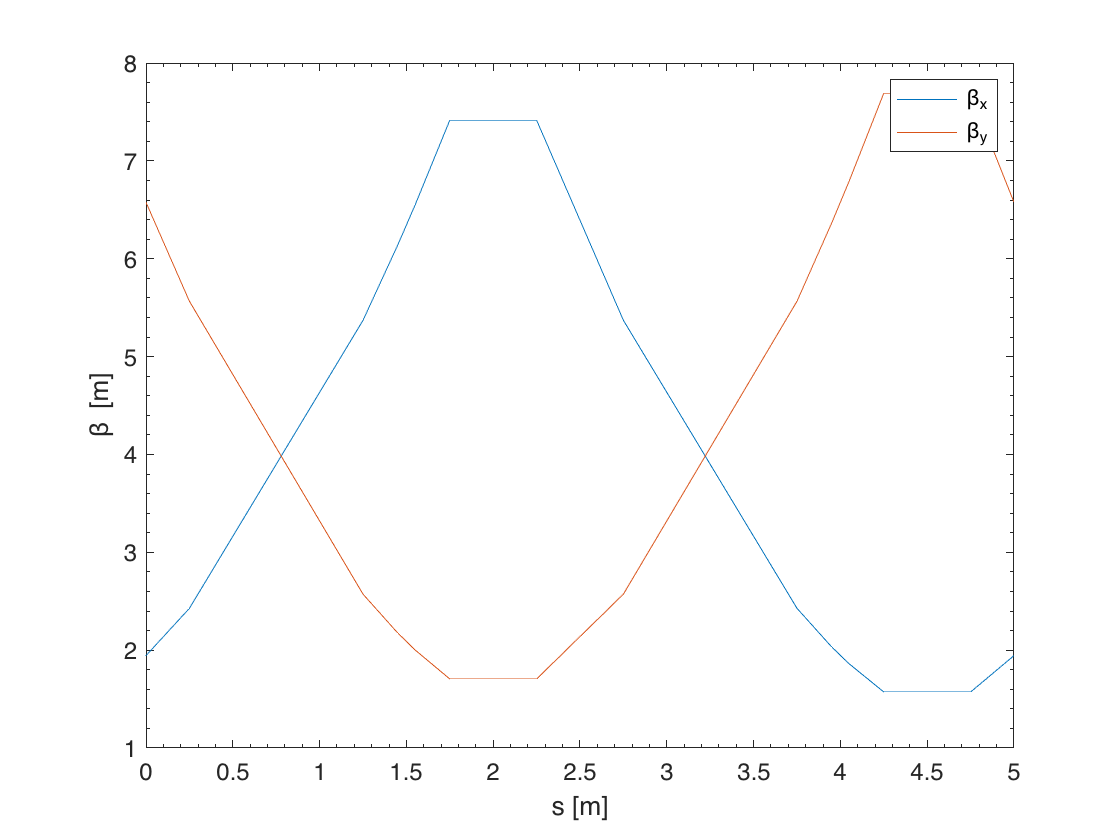

beta=cat(1,elemdata.beta);
spos=cat(1,elemdata.SPos);
figure
plot(spos,beta);
xlabel('s [m]');
ylabel('\beta [m]');
legend('\beta_x','\beta_y');

We may also plot the lattice parameters using a dedicated function called **atplot** with the command

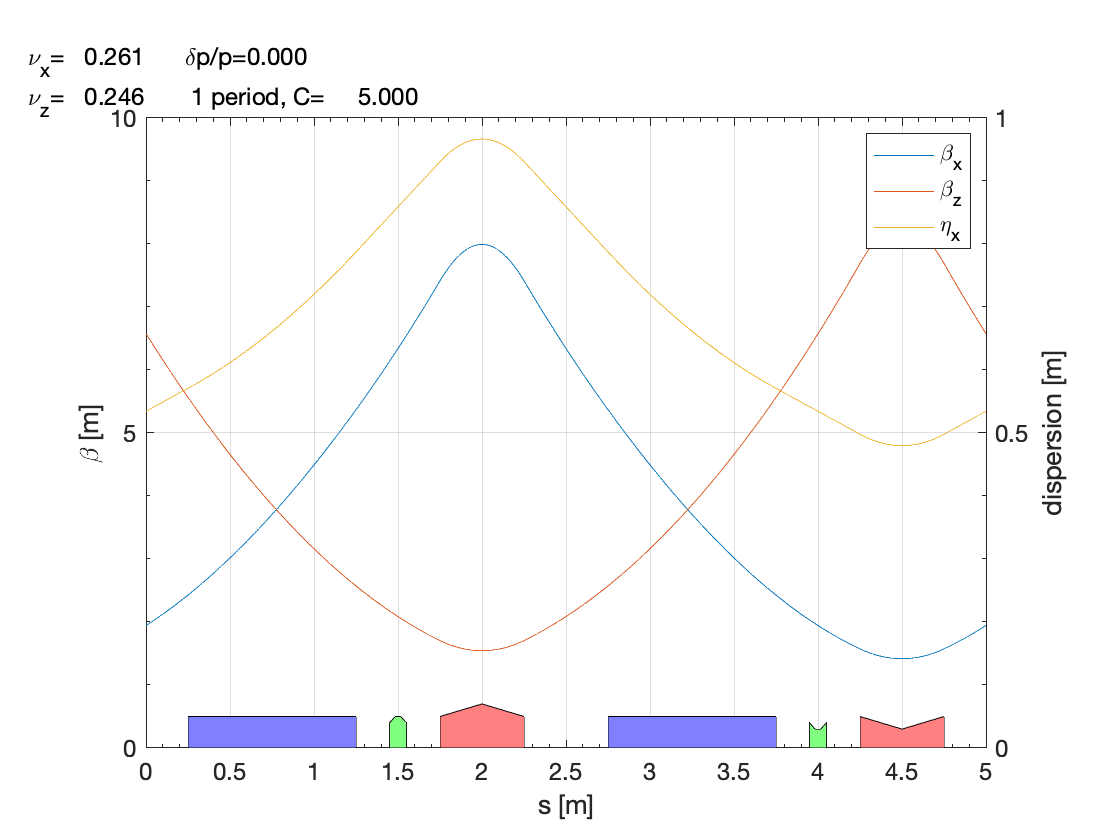

 atplot(FODOcellSext);

Note that the magnets are displayed below the function, giving a convenient visualization. Also note that the lattice functions are smoother than those we saw before. They have been computed at more positions, by slicing the magnets in the **atplot** function.

## Beam sizes

The parameters computed thus far use only the tracking through the lattice, with no radiation effects. In reality, for electrons, we know that there are radiation effects which cause a damping and diffusion and determine equilibrium emittances and beam sizes. This is computed in AT using the Ohmi envelope formalism. A simple interface to this code is provided via the function **atx** which gives the linear optics parameters we have just computed, and also the beam sizes.

In order to use **atx**, we first need to make sure the beam is stable longitudinally as well, requiring us to add an RF cavity to our FODO lattice. This is done with the command

RFC=atrfcavity('RFCav');

and the cavity is added to the lattice

FODOSextRF=[{RP;RFC};FODOSext(2:end)];

Now, we need to set the values of the RF cavity. This can be done with the function **atsetcavity** as follows

FODOSextRF=atsetcavity(FODOSextRF,'Frequency','nominal',...
    'Voltage',0.5e6,'HarmNumber',100);

which says that the RF cavity has a voltage of 0.5 MV and harmonic number of 100.

We may now call the function **atx** as follows

[elemdata,ringdata]=atx(FODOSextRF);
ringdata

ringdata = struct with fields:
              ll: 100.0000
           alpha: 0.0419
       fractunes: [0.2199 0.9178]
       fulltunes: [5.2199 4.9178]
             nuh: 5.2199
             nuv: 4.9178
    chromaticity: [0.4997 0.4997]
     dampingtime: [0.0536 0.0480 0.0228]
        dampingJ: [0.8951 1.0000 2.1049]
         espread: 3.3112e-04
         blength: 0.0121
    modemittance: [3.3651e-08 4.5621e-36 3.9994e-06]
          energy: 1.0000e+09
              fs: 5.4796e+04
           eloss: 1.3896e+04
    synchrophase: 0.0278
      momcompact: 0.0419


We see that our FODO lattice has an emittance of 33.65 nm, an energy spread of $$3.3\times 10^{-4}$$ and a bunch length of 12.1 mm.

## Bibliography

[[1]](https://www.slac.stanford.edu/pubs/slacpubs/8500/slac-pub-8732.pdf) A. Terebilo *Accelerator Toolbox for Matlab*, SLAC-PUB 8732 (May 2001)

[[2]](https://inspirehep.net/files/298dd81ab9ce89bfb2a42442b46b0379) A. Terebilo, *Accelerator Modelling with Matlab Accelerator Toolbox*, PAC 2001 Proceedings

[[3]](https://inspirehep.net/files/8507fec63dc914e41a782b13b831c64e) B. Nash *et al.*, *New Functionality for Beam Dynamics in Accelerator Toolbox*, IPAC 2015

[[4]](https://journals.aps.org/prab/pdf/10.1103/PhysRevSTAB.2.074001) D. Sagan, D. Rubin, *Linear Analysis of Coupled Lattices*, Phys. Rev. Special Topics - Accelerators and Beams, Vol 2,(1999) 